# Mission Analysis Walkthrough — highest fidelity

This live script computes the F-16A mission fuel with the **Level-2 (L2)** mission analysis over the **highest-fidelity** discipline models. It is the companion to `mission_analysis_L1_walkthrough.mlx`. It flies the same Combat Air Patrol (CAP) profile, so you can compare the two fidelities on the same mission.

The highest-fidelity discipline stack is: `F16AeroL3` for aerodynamics, `F16GeomL3` for geometry, and `F16PropL2` for propulsion. There is no L3 propulsion tier, so the engine numbers come from `F16PropL2`. There is no L3 mission tier either, so the L2 mission analysis runs over the L3 discipline stack.

Method reference: L2 uses Brandt's generic master mission-fuel equation, specialized per segment (Brandt F-16A workbook, Miss tab). Each master-form segment consumes the injected aero drag polar and the prop fuel consumption and thrust lapse. Segments the master form does not model fall back to the Roskam Table 2.1 constant fractions, so every segment still burns fuel.

This walkthrough does the following steps:

- it builds the L3 aerodynamics and geometry models and the L2 propulsion model

- it shows how the drag polar and the fuel consumption feed a cruise leg

- it flies the ten-segment CAP profile with the L2 method

- it reports the fuel burned by each segment

- it adds the reserve to get the total fuel

The coupled sizing loop solves for the takeoff weight that makes the fuel close. That loop is a separate pass. It is not shown here.

## Make the sizing framework visible

This block adds the framework to the MATLAB path. If you already ran `tests/run_all_tests`, the path is set and this block does nothing.

if isempty(which("f16a_spec_path"))
    try
        here = fileparts(matlab.desktop.editor.getActiveFilename);
    catch
        here = pwd;
    end
    root = here;
    while ~isfolder(fullfile(root, "src")) || ~isfolder(fullfile(root, "examples", "F16A"))
        parent = fileparts(root);
        if strcmp(parent, root)
            error("Could not find the sizing/ root. Add its src/, examples/, and VnV/ folders to the path, or run this file from inside air_vehicle_design/sizing.");
        end
        root = parent;
    end
    addpath(genpath(fullfile(root, "src")));
    addpath(genpath(fullfile(root, "examples")));
    addpath(genpath(fullfile(root, "VnV")));
end

## Build the highest-fidelity discipline models

The build order matters, because the objects depend on each other. First build the propulsion object. Then inject it into the geometry object, because the engine thrust sizes the nacelle. Then inject the geometry object into the aerodynamics object, because the L3 drag build-up reads the real planform live from geometry.

We fix the takeoff gross weight at Brandt's F-16A value, 31,377 lbf. In a full sizing run the loop would solve for this weight. Unlike L1, the L3 geometry computes its wetted area from the real planform, so it does not need the takeoff weight.

prop = F16PropL2(f16a_spec_path(2));
geom = F16GeomL3(f16a_spec_path(3), prop);
aero = F16AeroL3(geom, f16a_spec_path(3));
W_TO = 31377;

## What the models produce for a cruise leg

A cruise leg needs the fuel consumption and the lift-to-drag ratio. The fuel consumption comes from the prop object. The lift-to-drag ratio is built from the L3 aero drag polar, the geometry reference area, and the current weight.

The lift coefficient in level flight is $ C_L = W/(q S) $. The drag coefficient is $ C_D = C_{D0} + K_1 C_L^2 + K_2 C_L $, where at L3 the clean `CD0` is a component build-up. The ratio $ L/D = C_L/C_D $. This example uses cruise at 40,000 ft and Mach 0.87, at a representative mid-cruise weight.

cruise   = AircraftState(40000, 0.87);
W_cruise = 0.90 * W_TO;
CL = W_cruise / (cruise.q * geom.S_ref);
polar = aero.drag_polar(cruise);
CD = polar.CD0 + polar.K1*CL^2 + polar.K2*CL;
LD = CL / CD;
cruiseLD = table([CL; CD; LD; cruise.V], 'VariableNames', "Value", 'RowNames', ...
    {'CL  lift coefficient', 'CD  drag coefficient', 'L/D  lift-to-drag', 'V  true airspeed [ft/s]'})

cruiseLD = 4×1 table
                                Value  
                               ________

    CL  lift coefficient        0.45359
    CD  drag coefficient       0.037499
    L/D  lift-to-drag            12.096
    V  true airspeed [ft/s]      842.23


The propulsion object returns the fuel consumption at mil and afterburner power, plus the thrust lapse $ \alpha = T/T_{SL} $. A segment blends the mil and afterburner values by its afterburner setting.

propSummary = table([prop.get_TSFC(cruise); prop.compute_TSFC_AB(cruise); prop.thrust_lapse(cruise, "AB")], ...
    'VariableNames', "Value", 'RowNames', ...
    {'TSFC  mil [1/hr]', 'TSFC  afterburner [1/hr]', 'alpha  AB thrust lapse'})

propSummary = 3×1 table
                                 Value 
                                _______

    TSFC  mil [1/hr]             1.0067
    TSFC  afterburner [1/hr]      1.591
    alpha  AB thrust lapse      0.30314


The next table maps each model output to the place where it enters the mission.

## Build the mission

`MissionAnalysisL2.from_requirements` reads the CAP profile from `f16a_requirements.json` and injects the three discipline objects. The L2 method maps each segment type to a specialized master-form class, or to a fixed fraction where the master form does not apply.

mission = MissionAnalysisL2.from_requirements(aero, prop, geom, f16a_requirements_path(), "cap");

The combat leg is the clearest example of the master form. Its fuel is thrust times fuel consumption times time, $ W_f = c_t\, T\, t $, with the thrust lapsed to the combat altitude and Mach.

## Run the mission and read the fuel by segment

`total_fuel` threads the weight through the segments and returns the total fuel plus a breakdown. The breakdown carries the fuel per segment, the weight after each segment, and the drivers `L/D` and `TSFC`. The master-form legs report both drivers; the fixed-fraction legs report neither.

[W_fuel, bd] = mission.total_fuel(W_TO);
nSeg = numel(bd.names);
LD_seg = nan(nSeg,1); TSFC_seg = nan(nSeg,1);
for i = 1:nSeg
    d = bd.debug{i};
    if isfield(d, 'LD'),          LD_seg(i)   = d.LD;   end
    if isfield(d, 'TSFC_per_hr'), TSFC_seg(i) = d.TSFC_per_hr; end
end
segTable = table(bd.names(:), bd.fuel_lbf(:), bd.W_after(:), LD_seg, TSFC_seg, ...
    'VariableNames', ["Segment", "Fuel_lb", "Weight_after_lb", "L_over_D", "TSFC_per_hr"])

segTable = 10×5 table
     Segment     Fuel_lb    Weight_after_lb    L_over_D    TSFC_per_hr
    _________    _______    _______________    ________    ___________

    "Startup"    313.77          31063             NaN          NaN   
    "Taxi"       310.63          30753             NaN          NaN   
    "Takeoff"    91.003          30662             NaN          NaN   
    "Climb"      2098.4          28563          12.068       1.0753   
    "Cruise"     979.84          27583          12.068       1.0872   
    "Dash"       817.87          26765          4.2548       1.9029   
    "Combat"     799.93          21566          11.928       1.7848   
    "Cruise2"    1088.7          20477          12.528       1.0872   
    "Loiter"     575.21          19902           10.26       1.0349   
    "Landing"    99.508   

## Fuel by segment

The bar chart shows where the fuel goes. Compare the shape with the L1 chart. The L2 master form redistributes the burn, because it models the physics of each leg instead of a single historical fraction.

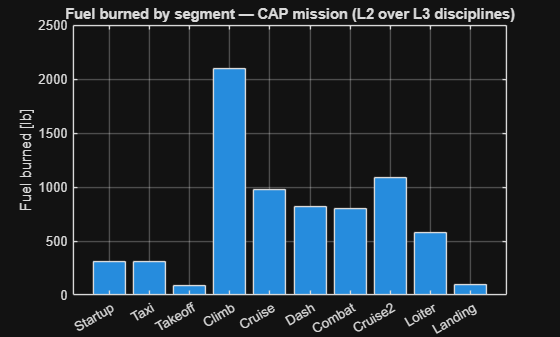

segCats = categorical(bd.names(:), bd.names(:));
bar(segCats, bd.fuel_lbf(:))
grid on
ylabel('Fuel burned [lb]')
title('Fuel burned by segment — CAP mission (L2 over L3 disciplines)')

## Totals and reserve

The raw burn is the sum of the segment fuels. The total fuel adds a reserve fraction on top: $ W_{fuel} = W_{raw}(1 + f_{res}) $, with $ f_{res} = 0.06 $ for this profile (Roskam Part I, Eq. 2.14 to 2.15).

totals = table([bd.raw_burn; bd.reserve_fuel_fraction; W_fuel], 'VariableNames', "Value", 'RowNames', ...
    {'Raw burn (sum of segments) [lb]', 'Reserve fraction', 'Total fuel with reserve [lb]'})

totals = 3×1 table
                                       Value 
                                       ______

    Raw burn (sum of segments) [lb]    7174.9
    Reserve fraction                     0.06
    Total fuel with reserve [lb]       7605.4


## A note on validation and the fuller profile

L2 also flies the fuller 14-segment Brandt profile. That profile adds accel, patrol, and egress legs that the L1 method cannot model. The informational report `examples/F16A/sanity_checks/mission_brandt_comparison.m` runs that profile and compares the raw burn against Brandt's ground truth of 6000.43 lb. It is a comparison report, not a pass/fail test, and it is where you check agreement with the workbook.

## Summary

The L3 aerodynamics model set the `L/D` from a real drag build-up. The L2 propulsion model set the fuel consumption at mil and afterburner power and the thrust lapse. The geometry model set the reference area and the engine count. The L2 master form used these to model each leg, and the fixed-fraction legs used historical fractions.

Set this fuel result beside the L1 result on the same CAP mission. The two differ because the analysis method and the discipline fidelity both changed. This is the value of a tiered framework: the same mission runs at the fidelity the study needs.

This run held the takeoff weight fixed. The coupled sizing loop instead solves for the takeoff weight. That loop is a separate pass and is not shown in this script.